# Brain states

Matlab live script for computer practical Neurophysics course

2024, Alexander Heimel

### Set path

First manually add path for folder containing this script.

rootpath = fileparts(which('brainstates.mlx'));
addpath(fullfile(rootpath,'General'));
addpath(fullfile(rootpath,'Mutualinfo'));
addpath(genpath(fullfile(rootpath,'pmtk3')));
disp('Added folders to path.')

Added folders to path.


## Load spike data

Load a dataset from a Neuropixels electrophysiology recording of mouse V1 units while the mouse is observing trials of drifting gratings of 12 different orientations.

params = bs_default_params();

[spike_times,trial_stim_on,trial_stim_off,trial_stim_type,recording_interval] = ...
    bs_load_data(params);

Loaded 127 clusters and 480 trials for 12 different stimuli.
Stimulus typeRunDriftingGratings


% spike_times contains a Nx1 cell list with vectors of spike times per unit
% trial_stim_on contains 1xM vectors with stimulus trial onset times
% recording_interval contains 1x2 vector with start and end of stimulus session

params.smooth = true;
params.smooth_function = 'smoothen';

% convert spike times to bin counts and smoothen data
[bin_times,bin_counts,bin_labels,bin_times_rel] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type,...
    recording_interval,params);
n_bins = length(bin_times);
% bin_times is 1 x n_bins vector with times of the center of the bins
% bin_counts is N x n_bins matrix with (smoothened) spike counts per bin and unit
% bin_labels is 1 x n_bins vector with stimulus labels
% bin_times_rel is 1 x n_bins vector with times relative to stimulus onsets

% create a subset of bins to speed up graphs and computations (especially for t-sne)
ind_bin_subset = round(linspace(1,n_bins,min([1000 n_bins]))); 

### Exercise Data.1

Plot cumultative spike count over time of a single neuron, for the recording interval.

### Exercise Data.2

Plot cumulative total spike count for the entire population over time, for the recording interval.

### Exercise Data.3

Show a heat plot of the rate (spike counts per time bin) for all units.

### Exercise Data.4

Show a heat plot of the rate for all units, normalized to the maximum rate per unit.

## Principal components analysis

Principal component analysis (PCA) is a linear dimensionality reduction technique with applications in exploratory data analysis, visualization and data preprocessing. The data is linearly transformed onto a new coordinate system such that the directions (principal components) capturing the largest variation in the data can be easily identified [[Source: https://en.wikipedia.org/wiki/Principal_component_analysis](https://en.wikipedia.org/wiki/Principal_component_analysis)].

## PCA Example with two neurons

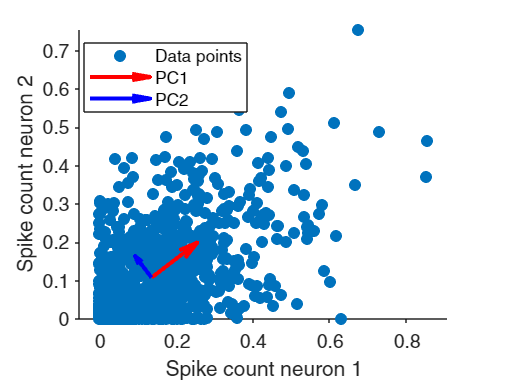

c1 = 15;
c2 = 19;
x = bin_counts([c1 c2],:)';
[coeff,score,latent] = pca(x); %#ok<ASGLU>

figure
scatter(bin_counts(c1,ind_bin_subset),...
    bin_counts(c2,ind_bin_subset) ,'filled')
xlabel('Spike count neuron 1');
ylabel('Spike count neuron 2');
axis equal

% Plot the first two principal components
hold on
x_mean = mean(x);
quiver(x_mean(1), x_mean(2), ...
       coeff(1, 1) * sqrt(latent(1)), coeff(2, 1) * sqrt(latent(1)), ...
       'r', 'LineWidth', 2, 'MaxHeadSize', 2);
quiver(x_mean(1), x_mean(2), ...
       coeff(1, 2) * sqrt(latent(2)), coeff(2, 2) * sqrt(latent(2)), ...
       'b', 'LineWidth', 2, 'MaxHeadSize', 2);
legend('Data points', 'PC1', 'PC2', 'Location', 'best');

## PCA for all clusters

x = bin_counts';
[coeff,score,~,~,explained] = pca(x);
x_mean = mean(x); 
disp('Computed PCA')

Computed PCA


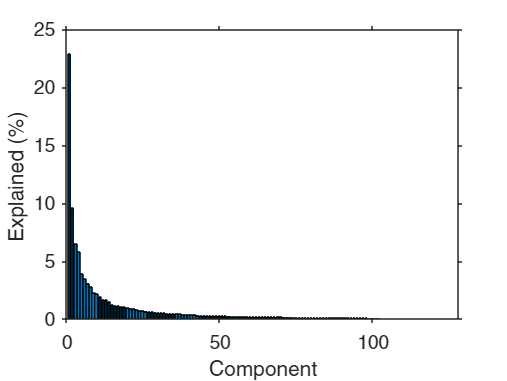

figure
bar(explained)
ylabel('Explained (%) ')
xlabel('Component')

%xlim([0.5 10.5])
%set(gca,'xtick',1:2:10)

### Excercise PCA.1

Reconstruct the data from the first 3 principal components. Show the original data and the reconstructed data as a heat plot.

## PC1 vs PC2 with time since stimulus on as color

figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_times_rel(ind_bin_subset),'filled')
axis square
colorbar
xlabel('PC1')
ylabel('PC2')

% Plot moving average
hold on
[~,ind] = sort(bin_times_rel);
x = movmean(score(ind,1),2000);
y = movmean(score(ind,2),2000);
plot(x,y,'k-','linewidth',10)
scatter(x,y,10,bin_times_rel(ind),'filled')

## PC1 vs PC2 with label as color

figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_labels(ind_bin_subset),'filled')
colormap(parula(max(bin_labels(ind_bin_subset))+2))

axis square
colorbar
xlabel('PC1')
ylabel('PC2')

% Plot moving average
hold on
[~,ind] = sort(bin_labels);
x = movmean(score(ind,1),2000);
y = movmean(score(ind,2),2000);
plot(x,y,'k-','linewidth',10)
scatter(x,y,10,bin_labels(ind),'filled')

## Factor analysis

Factor analysis is a statistical method used to describe variability among observed, correlated variables in terms of a potentially lower number of unobserved variables called factors. For example, it is possible that variations in six observed variables mainly reflect the variations in two unobserved (underlying) variables. Factor analysis searches for such joint variations in response to unobserved latent variables. The observed variables are modelled as linear combinations of the potential factors plus "error" terms, hence factor analysis can be thought of as a special case of errors-in-variables models [[Source: ](https://en.wikipedia.org/wiki/Factor_analysis)[https://en.wikipedia.org/wiki/Factor_analysis].](https://en.wikipedia.org/wiki/Factor_analysis].)

While PCA is used as a method to reduce the data, FA is used to find underlying correlations. Results can be similar but will not be identical. 

[~,~,~,~,score] = factoran(bin_counts',10);
disp('Computed Factor Analysis')

## First two factors with time since stimulus on as color

figure;
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_times_rel(ind_bin_subset),'filled')
axis square
colorbar
xlabel('Score 1')
ylabel('Score 2')
hold on

% Plot moving average
[~,ind] = sort(bin_times_rel);
x = movmean(score(ind,1),2000);
y = movmean(score(ind,2),2000);
plot(x,y,'k-','linewidth',10)
scatter(x,y,10,bin_times_rel(ind),'filled')

### Exercise FA.1

Plot first two factors with label as color

## Visualizing high-dimensional data - t-SNE

t-distributed stochastic neighbor embedding (t-SNE) is a nonlinear dimensionality reduction technique for embedding high-dimensional data for visualization in a low-dimensional space of two or three dimensions. Specifically, it models each high-dimensional object by a two- or three-dimensional point in such a way that similar objects are modeled by nearby points and dissimilar objects are modeled by distant points with high probability [[Source: https://en.wikipedia.org/wiki/T-distributed_stochastic_neighbor_embedding](https://en.wikipedia.org/wiki/T-distributed_stochastic_neighbor_embedding)]. A popular alternative is UMAP.

rng(1)
x_tsne = tsne(bin_counts(:,ind_bin_subset)');
disp('Computed t-sne')

### Show t-sne with time as color

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,bin_times(ind_bin_subset),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Absolute time')

### Show t-sne with time since stim onset as color

figure
c = bin_times_rel(ind_bin_subset);
scatter(x_tsne(:,1),x_tsne(:,2),30,c,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(periodic_colormap(128))
colorbar
title('Time since stim on')

### Show t-sne with stim type as color

figure
c = bin_labels(ind_bin_subset)+2;
scatter(x_tsne(:,1),x_tsne(:,2),30,c,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(parula(max(bin_labels(ind_bin_subset))+2))
colorbar
title('Stim type')

## Clustering - k-means

k-means clustering is a method of vector quantization, originally from signal processing, that aims to partition n observations into k clusters in which each observation belongs to the cluster with the nearest mean (cluster centers or cluster centroid), serving as a prototype of the cluster. This results in a partitioning of the data space into Voronoi cells. k-means clustering minimizes within-cluster variances (squared Euclidean distances) [[https://en.wikipedia.org/wiki/K-means_clustering](https://en.wikipedia.org/wiki/K-means_clustering)]. 

### Cluster based on t-sne transform

rng(1)
n_clusters = 10;
[idx_subset, centers] = kmeans(x_tsne,n_clusters);

### Show t-sne with cluster as color

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx_subset,'filled')
hold on
voronoi(centers(:,1),centers(:,2))
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(parula(n_clusters))
colorbar
title('Cluster')

### Kmeans of original data

rng(1);
idx = kmeans(bin_counts',n_clusters);
disp('Computed kmeans clusters')

### Show t-sne with cluster as color

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx(ind_bin_subset),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(parula(n_clusters))
colorbar
title('Cluster')

### Exercise Tsne.1

Remove outlying cluster and run t-sne again

## Gaussian mixture

A gaussian mixture model assumes the data to be generated from a mixture of gaussian probability distributions. The gaussians will have different means and covariances. 

n_clusters = 10;
gmfit = fitgmdist(x_tsne,n_clusters,'CovarianceType','full','RegularizationValue',0.1,'Options',statset('MaxIter',500));
post = posterior(gmfit,x_tsne);
idx_gm = cluster(gmfit,x_tsne);
disp('Computed mixture of Gaussians')

### Show clusters with maximum likelihood

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,idx_gm,'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colormap(parula(n_clusters))
colorbar
title('Cluster with max. likelihood')

### Exercise GM.1

Show likelihood of cluster 1

## Hidden Markov Models

A Hidden Markov Model (HMM) is a set of states and transition probabilities to change from one state to another at each time step. At each time step, an emission (observation) is generated, chosen with a probability distribution that depends on the state [[https://en.wikipedia.org/wiki/Hidden_Markov_model](https://en.wikipedia.org/wiki/Hidden_Markov_model)]. A nice reference for fitting an HMM to neural data is Bagi et al. (Curr Biol 2022).

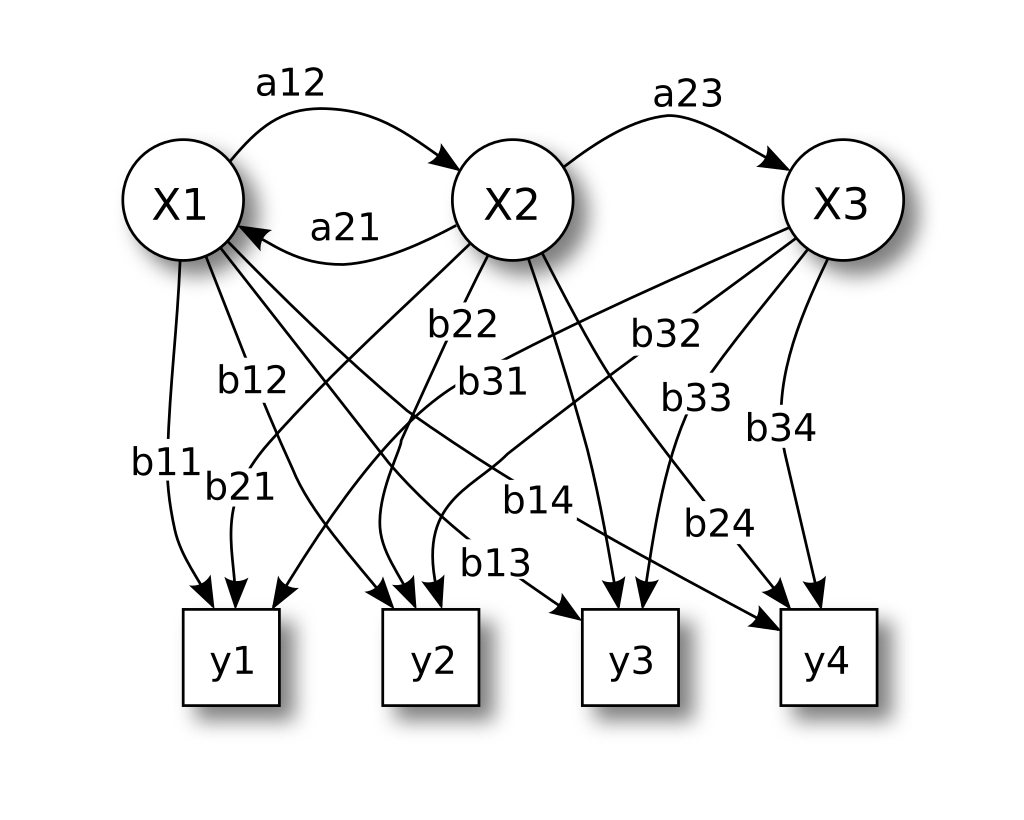

Matlab has in-built functions for training and decoding an HMM (e.g. hmmtrain). 

### Two state HMM on trial structure with hint

% Example in which we assume the stimulus labels are the observations made at each time bin.
% Between all stimuli, there are time bins with an empty label.

params = bs_default_params();
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type,recording_interval,params);

trans_guess = [ ... % n_states x n_states
    0.99 0.01; ...
    0.01 0.99];
emis_guess = [...
    0 0 0 0 0 0 0 0 0 0 0 0 1; ...
    1 1 1 1 1 1 1 1 1 1 1 1 0];

bin_data = bin_labels;
bin_data(bin_data==params.empty_label) = 13;

[trans,emis] = hmmtrain(bin_data,trans_guess,emis_guess);
p_states = hmmdecode(bin_data,trans,emis);
[~,bin_states] = max(p_states);

bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on trial labels without hint

params = bs_default_params();
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = ...
    bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);

bin_data = bin_labels;
bin_data(bin_data==params.empty_label) = 13;

trans_guess = [0.9 0.1; 0.1 0.9];
emis_guess = rand(n_states,13);
emis_guess = emis_guess ./ sum(emis_guess,2);

[trans,emis] = hmmtrain(bin_data,trans_guess,emis_guess);
p_states = hmmdecode(bin_data,trans,emis);
[~,bin_states] = max(p_states);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on spike counts (overfitting)

n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
params.binsize = 0.1;
params.smooth = false;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)), recording_interval,params);
n_emissions = length(bin_times);

bin_clusters = kmeans(bin_counts',n_emissions);
[bin_states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on spike counts with hint

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';

[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);

bin_clusters = kmeans(bin_counts',n_emissions);

[bin_states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on first 10 PCs with hint

n_emissions = 100;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';

[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);

[~,bin_scores] = pca(bin_counts','NumComponents',10);

bin_clusters = kmeans(bin_scores,n_emissions);

[bin_states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM on first 10 FA components

n_emissions = 100;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'emission_freqs';
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);

[~,~,~,~,bin_scores] = factoran(bin_counts',10);

bin_clusters = kmeans(bin_scores,n_emissions,'MaxIter',500);

[bin_states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state HMM without hint

n_emissions = 10;
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'no_hints';
params.smooth = false;
params.binsize = 0.1;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);

bin_clusters = kmeans(bin_counts',n_emissions);

[bin_states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### HMM fit to all labels, no hints 

% Take about 1.5 minute, result 26%
n_emissions = 100; 
params = bs_default_params();
params.fit_hmm_prompt = 'no_hints';
params.smooth = false;
params.binsize = 0.1;
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
labels = unique(bin_labels);
n_states = length(labels);

bin_clusters = kmeans(bin_counts',n_emissions);

[states,~,trans,emis] = bs_fit_hmm(bin_clusters,n_states,n_emissions,[],bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,states,bin_times_rel);

## Gaussian mixture - Hidden Markov Model (GM-HMM)

Gaussian Mixture Hidden Markov Model are a type of HMMs where each state generates emissions from a different mixture of gaussians probability distribution. Matlab has no inbuilt gm-hmm. Here, we are using the extensive implementation from [https://github.com/probml/pmtk3/tree/master/toolbox/LatentVariableModels/hmm](https://github.com/probml/pmtk3/tree/master/toolbox/LatentVariableModels/hmm).

### Two state GM-HMM on first 10 FA components

% Takes about 1 min, result 49%
n_emissions = 10; % number of gaussians
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'mix_gauss_hints';
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[~,~,~,~,score] = factoran(bin_counts',10);
[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,'gm',bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

### Two state GM-HMM without hint

% Takes about 1 min, result 6%
n_emissions = 20; % number of gaussians
n_states = 2;
params = bs_default_params();
params.fit_hmm_prompt = 'no_mix_gauss_hints';
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,ones(size(trial_stim_type)),recording_interval,params);
[~,~,~,~,score] = factoran(bin_counts',10);
[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,'gm',bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## GM-HMM on first 10 FA components with hint

% Takes about 3 min, result 25%
n_emissions = 10; % number of gaussians
params = bs_default_params();
params.fit_hmm_prompt = 'mix_gauss_hints';
[bin_times,bin_counts,bin_labels,bin_times_rel,~] = bs_bin_labeled_data(spike_times,trial_stim_on,trial_stim_off,trial_stim_type, recording_interval,params);
labels = unique(bin_labels);
n_states = length(labels);
[~,~,~,~,score] = factoran(bin_counts',10);
[bin_states,~,trans,emis] = bs_fit_hmm(score',n_states,n_emissions,'gm',bin_labels,params);
bs_results_hmm(trans,emis,bin_times,bin_labels,bin_states,bin_times_rel);

## Solutions

### Solution Data.1

plot(spike_times{1},1:length(spike_times{1}));
xlim(recording_interval);
xlabel('Time (s)');
ylabel('Spike count');

### Solution Data.2

all_spikes = sort(vertcat(spike_times{:}));  
plot(all_spikes,1:length(all_spikes));
xlim(recording_interval);
xlabel('Time (s)');
ylabel('Spike count');


### Solution Data.3

imagesc(bin_counts,'XData',bin_times)
xlabel('Time (s)')
ylabel('Unit')


### Solution Data.4

bin_counts_norm = bin_counts ./ max(bin_counts,[],2);
imagesc(bin_counts_norm,'XData',bin_times)
xlabel('Time (s)')
ylabel('Neuron')

### Solution PCA.1

x_reconstruct = score(:,(1:3))*coeff(:,(1:3))' + repmat(x_mean,n_bins,1);
imagesc(x_reconstruct')

figure
subplot(1,2,1)
imagesc(x')
ylabel('Neuron')
xlabel('Sample')
title('Original data')

subplot(1,2,2)
imagesc(x_reconstruct')
ylabel('Neuron')
xlabel('Sample')
title('First 3 PCs')

### Solution FA.1

figure
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_labels(ind_bin_subset),'filled')
colormap(parula(max(bin_labels(ind_bin_subset))+2))
axis square
colorbar
xlabel('Score 1')
ylabel('Score 2')
hold on

% Plot moving average
[~,ind] = sort(bin_labels);
x = movmean(score(ind,1),2000);
y = movmean(score(ind,2),2000);
plot(x,y,'k-','linewidth',10)
scatter(x,y,10,bin_labels(ind),'filled')

### Solution Tsne.1

rng(1)
ind_bin_subset_cleaned = ind_bin_subset(idx_subset~=1);
x_tsne_cleaned = tsne(bin_counts(:,ind_bin_subset_cleaned)');

figure
c = bin_times_rel(ind_bin_subset_cleaned)';
scatter(x_tsne_cleaned(:,1),x_tsne_cleaned(:,2),30,c,'filled')
colormap(periodic_colormap(128))
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Time since stim on')

### Solution GM.1

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,post(:,1),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Likelihood cluster 1')
